## 数据导入-陕西省

filename = 'D:\Drivers\CarbonEmissiondata\Shaanxi_data.xlsx'; 
dataTable = readtable(filename);
%years = data.Year;  

% 对二氧化碳排放量进行插值CarbonEmissions_mt 缺少2019年的碳排放，使用三次样条计算后得到331.31
%carbonEmissionsIndex = ~ismissing(data.CarbonEmissions_mt); 
%data.CarbonEmissions_mt(carbonEmissionsIndex == 0) = interp1(years(carbonEmissionsIndex), data.CarbonEmissions_mt(carbonEmissionsIndex), years(carbonEmissionsIndex == 0), 'spline');

dataGDP_ren = dataTable.Per_capita_GDP_yuan(1:25);
dataGDP = dataGDP_ren.';

dataPopulation_wan = dataTable.Population_wan(1:25);
dataPopulation = dataPopulation_wan.';
disp(dataPopulation)

        3617        3626        3635        3644        3653        3662        3672        3681        3690        3699        3708        3718        3727        3735        3765        3787        3804        3827        3846        3874        3904        3931        3944        3955        3954



dataSecond_billion = dataTable.Value_added_of_the_secondary_industry_billion(1:25);
dataSecond = dataSecond_billion.';

dataCE_mt = dataTable.CarbonEmissions_mt(1:25);
%dataCE = dataCE_mt.';

dataCoal_tons = dataTable.Coal_consumption_10000_tons(1:25);
dataCoke_tons = dataTable.Coke_consumption_10000_tons(1:25);
dataFuel_tons = dataTable.Fuel_oil_consumption_10000_tons(1:25);
energyconsumption= (dataCoal_tons+dataCoke_tons+dataFuel_tons);
dataEnergy = energyconsumption.';
disp(dataEnergy)

   1.0e+04 *

    0.4174    0.4085    0.3635    0.3422    0.3879    0.4331    0.5020    0.6281    0.7543    0.9177    0.9910    1.1094    1.2022    1.4474    1.6207    1.8937    2.0414    2.1600    2.1445    2.2335    2.2753    2.2029    2.4137    2.4358    2.5050




dataNatural_meters = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25);
dataNaturalgas = dataNatural_meters.';

dataTechnology_million = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25);
dataTechnology = dataTechnology_million.';

%dataFirepower_kilowatt= dataTable.Thermal_power_generation_100_million_kilowatt_hours(1:26);
%dataFire = dataFirepower_kilowatt.';

dataWaterpower_kilowatt= dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25);
%dataWater = dataWaterpower_kilowatt.';

dataTotalpower_kilowatt= dataTable.Total_power_generation_100_million_kilowatt_hours(1:25);
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_2=(dataWaterpower_kilowatt/dataTotalpower_kilowatt);
%dataWaterpercent=dataWaterpercent_2.';


## 人均GDP的LSTM模型

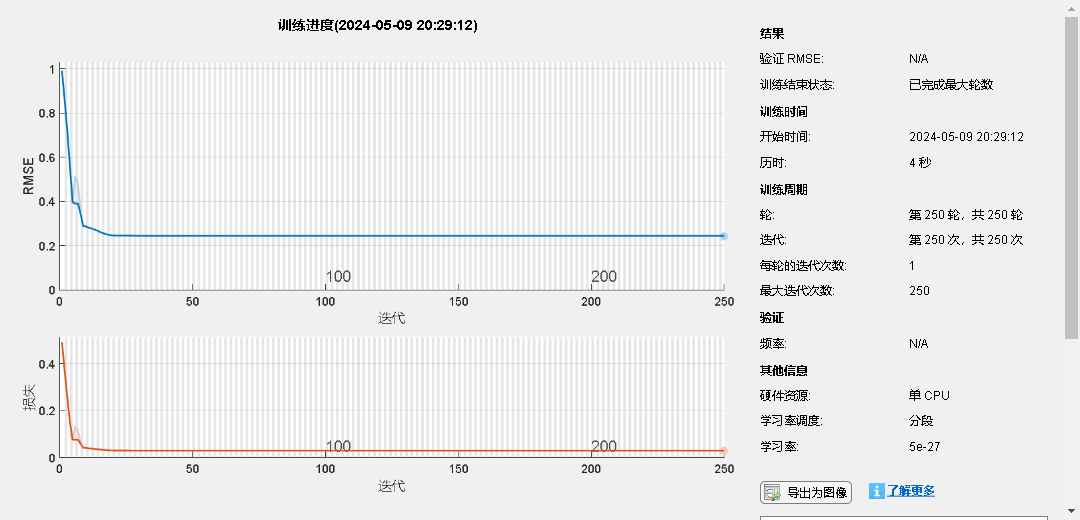

numTimeStepsTrain = numel(dataGDP); 
dataTrainGDP = dataGDP(1 : numTimeStepsTrain);
% 数据标准化，零均值和单位方差
muGDP = mean(dataTrainGDP);
sigGDP = std(dataTrainGDP);
dataTrainStandardizedGDP = (dataTrainGDP - muGDP) / sigGDP;
% 训练数据
XTrainGDP = dataTrainStandardizedGDP(1:end-1);
YTrainGDP = dataTrainStandardizedGDP(2:end);
% 创建 LSTM 网络
numFeaturesGDP = 1;
numResponsesGDP = 1;
numHiddenUnitsGDP = 100;

layersGDP = [sequenceInputLayer(numFeaturesGDP)
          lstmLayer(numHiddenUnitsGDP)
          fullyConnectedLayer(numResponsesGDP)
          regressionLayer];

% 设置网络参数
optionsGDP = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netGDP = trainNetwork(XTrainGDP, YTrainGDP, layersGDP, optionsGDP);

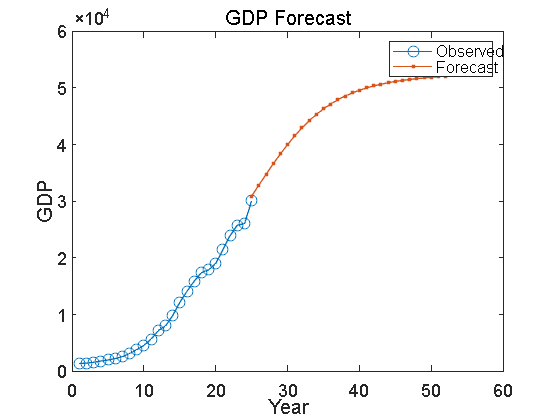

% 预测
netGDP = predictAndUpdateState(netGDP, XTrainGDP);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netGDP, YPredGDP] = predictAndUpdateState(netGDP, YTrainGDP(end));

% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictGDP = 28;
YPredGDP = [YPredGDP zeros(1, numYearsToPredictGDP - 1)]; % 预分配预测数组
for i = 2:numYearsToPredictGDP
    [netGDP, YPredGDP(:, i)] = predictAndUpdateState(netGDP, YPredGDP(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPredGDP = sigGDP * YPredGDP + muGDP;
% 画图
figure;
plot(1:numel(dataGDP), dataGDP, '-o')
hold on
idx = numel(dataGDP) : (numel(dataGDP) + numYearsToPredictGDP - 1);
plot(idx, YPredGDP, '.-')
hold off 
xlabel("Year");
ylabel("GDP");
title("GDP Forecast");
legend("Observed", "Forecast");

%writematrix(YPred, 'D:\Drivers\LSTM_liaoningCEdata.xlsx'); % 修改为实际文件路径
disp(YPredGDP)

   1.0e+04 *

    3.0916    3.2856    3.4749    3.6585    3.8340    3.9992    4.1523    4.2920    4.4178    4.5298    4.6284    4.7145    4.7892    4.8538    4.9093    4.9571    4.9981    5.0333    5.0635    5.0894    5.1117    5.1309    5.1475    5.1618    5.1741    5.1848    5.1941    5.2022



## 人口的LSTM模型

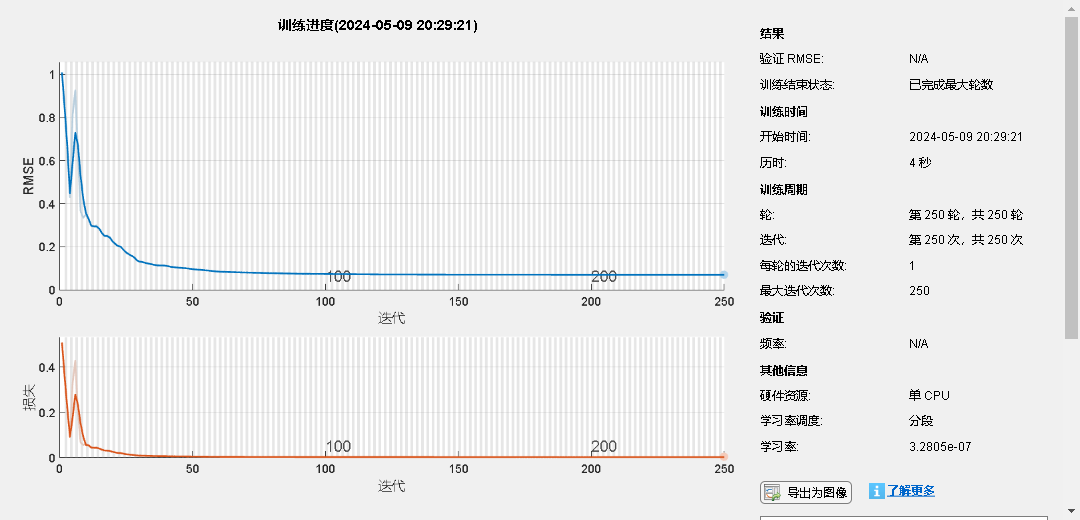

numTimeStepsTrainPopulation = numel(dataPopulation); % 使用所有的数据来训练
dataTrainPopulation = dataPopulation(1 : numTimeStepsTrainPopulation);

% 数据标准化，零均值和单位方差
muPopulation = mean(dataTrainPopulation);
sigPopulation = std(dataTrainPopulation);
dataTrainStandardizedPopulation = (dataTrainPopulation - muPopulation) / sigPopulation;

% 训练数据
XTrainPopulation = dataTrainStandardizedPopulation(1:end-1);
YTrainPopulation = dataTrainStandardizedPopulation(2:end);

% 创建 LSTM 网络
numFeaturesPopulation = 1;
numResponsesPopulation = 1;
numHiddenUnitsPopulation = 120;

layersPopulation = [sequenceInputLayer(numFeaturesPopulation)
          lstmLayer(numHiddenUnitsPopulation)
          fullyConnectedLayer(numResponsesPopulation)
          regressionLayer];

% 设置网络参数
optionsPopulation = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 30, ...
    'LearnRateDropFactor', 0.3, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netPopulation = trainNetwork(XTrainPopulation, YTrainPopulation, layersPopulation, optionsPopulation);

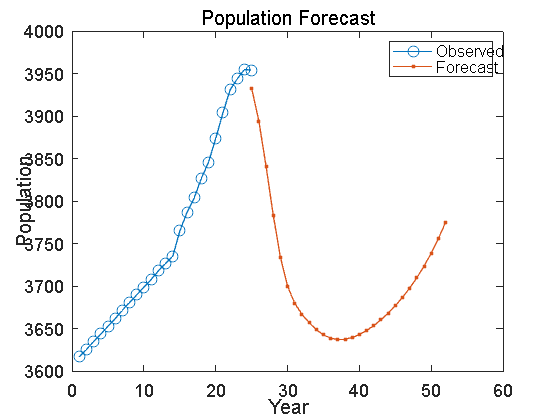


% 预测
netPopulation = predictAndUpdateState(netPopulation, XTrainPopulation);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netPopulation, YPredPopulation] = predictAndUpdateState(netPopulation, YTrainPopulation(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictPopulation = 28;
YPredPopulation = [YPredPopulation zeros(1, numYearsToPredictPopulation - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictPopulation
    [netPopulation, YPredPopulation(:, i)] = predictAndUpdateState(netPopulation, YPredPopulation(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredPopulation = sigPopulation * YPredPopulation + muPopulation;
% 画图
figure;
plot(1:numel(dataPopulation), dataPopulation, '-o')
hold on
idx = numel(dataPopulation) : (numel(dataPopulation) + numYearsToPredictPopulation - 1);
plot(idx, YPredPopulation, '.-')
hold off 
xlabel("Year");
ylabel("Population");
title("Population Forecast");
legend("Observed", "Forecast");

disp(YPredPopulation)

   1.0e+03 *

    3.9327    3.8941    3.8413    3.7838    3.7341    3.7000    3.6798    3.6671    3.6572    3.6490    3.6428    3.6390    3.6374    3.6378    3.6398    3.6432    3.6479    3.6537    3.6605    3.6683    3.6771    3.6869    3.6979    3.7101    3.7237    3.7390    3.7561    3.7753



## 第二产业的LSTM模型

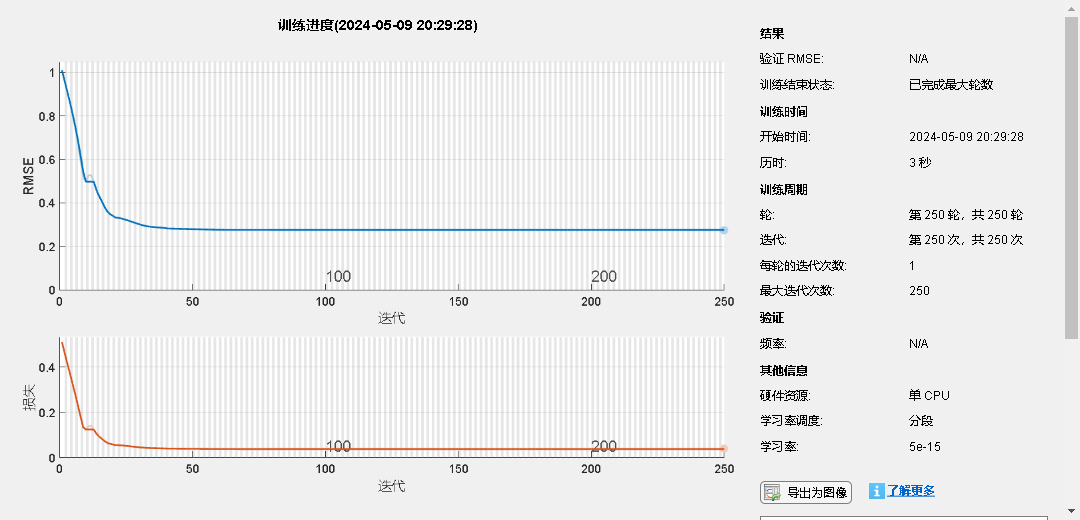

numTimeStepsTrainSecond = numel(dataSecond); 
dataTrainSecond = dataSecond(1 : numTimeStepsTrainSecond);

% 数据标准化，零均值和单位方差
musecond = mean(dataTrainSecond);
sigsecond = std(dataTrainSecond);
dataTrainStandardizedSecond = (dataTrainSecond - musecond) / sigsecond;

% 训练数据
XTrainSecond = dataTrainStandardizedSecond(1:end-1);
YTrainSecond = dataTrainStandardizedSecond(2:end);

% 创建 LSTM 网络
numFeaturesSecond= 1;
numResponsesSecond = 1;
numHiddenUnitsSecond = 40;

layersSecond = [sequenceInputLayer(numFeaturesSecond)
          lstmLayer(numHiddenUnitsSecond)
          fullyConnectedLayer(numResponsesSecond)
          regressionLayer];

% 设置网络参数
optionsSecond = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netSecond = trainNetwork(XTrainSecond, YTrainSecond, layersSecond, optionsSecond);

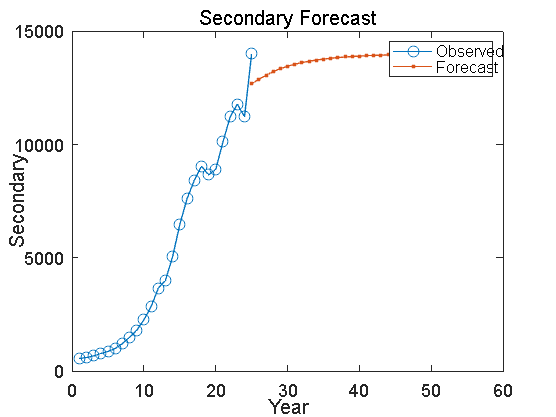


% 预测
netSecond = predictAndUpdateState(netSecond, XTrainSecond);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netSecond, YPredSecond] = predictAndUpdateState(netSecond, YTrainSecond(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictSecond = 28;
YPredSecond = [YPredSecond zeros(1, numYearsToPredictSecond - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictSecond
    [netSecond, YPredSecond(:, i)] = predictAndUpdateState(netSecond, YPredSecond(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredSecond = sigsecond * YPredSecond + musecond;
% 画图
figure;
plot(1:numel(dataSecond), dataSecond, '-o')
hold on
idx = numel(dataSecond) : (numel(dataSecond) + numYearsToPredictSecond - 1);
plot(idx, YPredSecond, '.-')
hold off 
xlabel("Year");
ylabel("Secondary");
title("Secondary Forecast");
legend("Observed", "Forecast");

disp(YPredSecond)

   1.0e+04 *

    1.2681    1.2869    1.3058    1.3216    1.3345    1.3452    1.3540    1.3613    1.3673    1.3724    1.3767    1.3803    1.3833    1.3859    1.3880    1.3899    1.3915    1.3928    1.3940    1.3950    1.3958    1.3966    1.3972    1.3977    1.3982    1.3986    1.3990    1.3993



## 煤炭等化石能源消耗量的LSTM模型

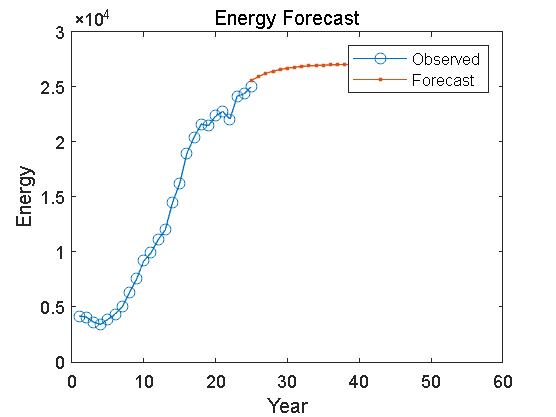

numTimeStepsTrainEnergy = numel(dataEnergy); 
dataTrainEnergy = dataEnergy(1 : numTimeStepsTrainEnergy);

% 数据标准化，零均值和单位方差
muEnergy = mean(dataTrainEnergy);
sigEnergy = std(dataTrainEnergy);
dataTrainStandardizedEnergy = (dataTrainEnergy - muEnergy) / sigEnergy;

% 训练数据
XTrainEnergy = dataTrainStandardizedEnergy(1:end-1);
YTrainEnergy = dataTrainStandardizedEnergy(2:end);

% 创建 LSTM 网络
numFeaturesEnergy= 1;
numResponsesEnergy = 1;
numHiddenUnitsEnergy = 100;

layersEnergy = [sequenceInputLayer(numFeaturesEnergy)
          lstmLayer(numHiddenUnitsEnergy)
          fullyConnectedLayer(numResponsesEnergy)
          regressionLayer];

% 设置网络参数
optionsEnergy = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同化石能源消耗背景下，改这个就行LearnRateDropFactor'
% 训练
netEnergy = trainNetwork(XTrainEnergy, YTrainEnergy, layersEnergy, optionsEnergy);

% 预测
netEnergy = predictAndUpdateState(netEnergy, XTrainEnergy);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netEnergy, YPredEnergy] = predictAndUpdateState(netEnergy, YTrainEnergy(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictEnergy = 28;
YPredEnergy = [YPredEnergy zeros(1, numYearsToPredictEnergy - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictEnergy
    [netEnergy, YPredEnergy(:, i)] = predictAndUpdateState(netEnergy, YPredEnergy(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredEnergy = sigEnergy * YPredEnergy + muEnergy;
% 画图
figure;
plot(1:numel(dataEnergy), dataEnergy, '-o')
hold on
idx = numel(dataEnergy) : (numel(dataEnergy) + numYearsToPredictEnergy - 1);
plot(idx, YPredEnergy, '.-')
hold off 
xlabel("Year");
ylabel("Energy");
title("Energy Forecast");
legend("Observed", "Forecast");

disp(YPredEnergy)

   1.0e+04 *

    2.5552    2.5926    2.6203    2.6408    2.6560    2.6675    2.6762    2.6828    2.6879    2.6918    2.6949    2.6974    2.6993    2.7009    2.7021    2.7031    2.7040    2.7046    2.7052    2.7056    2.7060    2.7063    2.7065    2.7067    2.7069    2.7071    2.7072    2.7073



## 天然气的LSTM模型

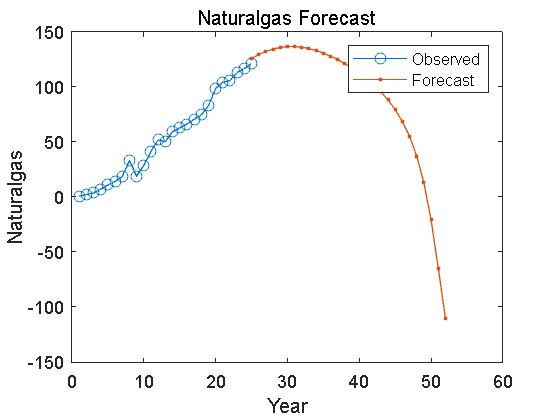

numTimeStepsTrainNaturalgas = numel(dataNaturalgas);
dataTrainNaturalgas = dataNaturalgas(1 : numTimeStepsTrainNaturalgas);

% 数据标准化，零均值和单位方差
muNaturalgas = mean(dataTrainNaturalgas);
sigNaturalgas = std(dataTrainNaturalgas);
dataTrainStandardizedNaturalgas = (dataTrainNaturalgas - muNaturalgas) / sigNaturalgas;

% 训练数据
XTrainNaturalgas = dataTrainStandardizedNaturalgas(1:end-1);
YTrainNaturalgas = dataTrainStandardizedNaturalgas(2:end);

% 创建 LSTM 网络
numFeaturesNaturalgas= 1;
numResponsesNaturalgas = 1;
numHiddenUnitsNaturalgas = 100;

layersNaturalgas = [sequenceInputLayer(numFeaturesNaturalgas)
          lstmLayer(numHiddenUnitsNaturalgas)
          fullyConnectedLayer(numResponsesNaturalgas)
          regressionLayer];

% 设置网络参数
optionsNaturalgas = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Naturalgas背景下，改这个就行LearnRateDropFactor'
% 训练
netNaturalgas = trainNetwork(XTrainNaturalgas, YTrainNaturalgas, layersNaturalgas, optionsNaturalgas);

% 预测
netNaturalgas = predictAndUpdateState(netNaturalgas, XTrainNaturalgas);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netNaturalgas, YPredNaturalgas] = predictAndUpdateState(netNaturalgas, YTrainNaturalgas(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictNaturalgas = 28;
YPredNaturalgas = [YPredNaturalgas zeros(1, numYearsToPredictNaturalgas - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictNaturalgas
    [netNaturalgas, YPredNaturalgas(:, i)] = predictAndUpdateState(netNaturalgas, YPredNaturalgas(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredNaturalgas = sigNaturalgas * YPredNaturalgas + muNaturalgas;
% 画图
figure;
plot(1:numel(dataNaturalgas), dataNaturalgas, '-o')
hold on
idx = numel(dataNaturalgas) : (numel(dataNaturalgas) + numYearsToPredictNaturalgas - 1);
plot(idx, YPredNaturalgas, '.-')
hold off 
xlabel("Year");
ylabel("Naturalgas");
title("Naturalgas Forecast");
legend("Observed", "Forecast");

disp(YPredNaturalgas)

  125.3931  129.0123  131.9333  134.1252  135.5813  136.3153  136.3558  135.7408  134.5150  132.7266  130.4239  127.6505  124.4401  120.8119  116.7641  112.2696  107.2684  101.6583   95.2795   87.8892   79.1185   68.3981   54.8305   36.9836   12.6450  -21.0070  -64.7894 -110.5770



## 科技发展LSTM模型

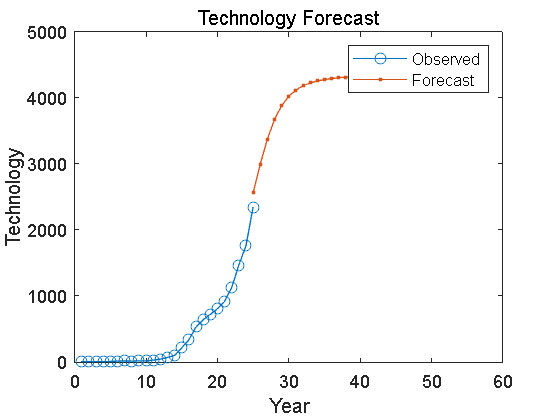

numTimeStepsTrainTechnology = numel(dataTechnology); 
dataTrainTechnology = dataTechnology(1 : numTimeStepsTrainTechnology);

% 数据标准化，零均值和单位方差
muTechnology = mean(dataTrainTechnology);
sigTechnology = std(dataTrainTechnology);
dataTrainStandardizedTechnology = (dataTrainTechnology - muTechnology) / sigTechnology;

% 训练数据
XTrainTechnology = dataTrainStandardizedTechnology(1:end-1);
YTrainTechnology = dataTrainStandardizedTechnology(2:end);

% 创建 LSTM 网络
numFeaturesTechnology= 1;
numResponsesTechnology = 1;
numHiddenUnitsTechnology = 100;

layersTechnology = [sequenceInputLayer(numFeaturesTechnology)
          lstmLayer(numHiddenUnitsTechnology)
          fullyConnectedLayer(numResponsesTechnology)
          regressionLayer];

% 设置网络参数
optionsTechnology = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.01, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，改这个就'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netTechnology = trainNetwork(XTrainTechnology, YTrainTechnology, layersTechnology, optionsTechnology);

% 预测
netTechnology = predictAndUpdateState(netTechnology, XTrainTechnology);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netTechnology, YPredTechnology] = predictAndUpdateState(netTechnology, YTrainTechnology(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictTechnology = 28;
YPredTechnology = [YPredTechnology zeros(1, numYearsToPredictTechnology - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictTechnology
    [netTechnology, YPredTechnology(:, i)] = predictAndUpdateState(netTechnology, YPredTechnology(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredTechnology = sigTechnology * YPredTechnology + muTechnology;
% 画图
figure;
plot(1:numel(dataTechnology), dataTechnology, '-o')
hold on
idx = numel(dataTechnology) : (numel(dataTechnology) + numYearsToPredictTechnology - 1);
plot(idx, YPredTechnology, '.-')
hold off 
xlabel("Year");
ylabel("Technology");
title("Technology Forecast");
legend("Observed", "Forecast");

disp(YPredTechnology)

   1.0e+03 *

    2.5576    2.9941    3.3739    3.6684    3.8781    4.0203    4.1149    4.1783    4.2215    4.2516    4.2731    4.2888    4.3005    4.3094    4.3163    4.3217    4.3259    4.3293    4.3321    4.3344    4.3362    4.3378    4.3391    4.3402    4.3411    4.3419    4.3426    4.3432



## 水力发电的百分占比LSTM模型

dataWaterpercent_2= dataTable.WaterPercent(1:25);
dataWaterpercent_1=dataWaterpercent_2*100;
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_1=(dataWaterpower_kilowatt / dataTotalpower_kilowatt)*100;
dataWaterpercent=dataWaterpercent_1.';
disp(dataWaterpercent);

   1.0e+04 *

    0.2247    0.3120    0.1968    0.3480    1.4914    0.2592    0.4675    0.4249    0.5054    0.3988    0.5545    0.6423    0.7459    0.8724    0.9963    0.7988    1.1087    1.1298    1.3426    1.2514    1.4213    1.3611    1.5498    1.2811    1.3173



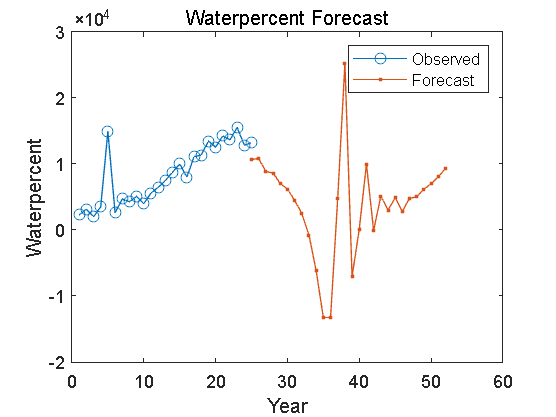


numTimeStepsTrainWaterpercent = numel(dataWaterpercent); % 使用所有的数据来训练
dataTrainWaterpercent = dataWaterpercent(1 : numTimeStepsTrainWaterpercent);

% 数据标准化，零均值和单位方差
muWaterpercent = mean(dataTrainWaterpercent);
sigWaterpercent = std(dataTrainWaterpercent);
dataTrainStandardizedWaterpercent = (dataTrainWaterpercent - muWaterpercent) / sigWaterpercent;

% 训练数据
XTrainWaterpercent = dataTrainStandardizedWaterpercent(1:end-1);
YTrainWaterpercent = dataTrainStandardizedWaterpercent(2:end);

% 创建 LSTM 网络
numFeaturesWaterpercent= 1;
numResponsesWaterpercent = 1;
numHiddenUnitsWaterpercent = 130;

layersWaterpercent = [sequenceInputLayer(numFeaturesWaterpercent)
          lstmLayer(numHiddenUnitsWaterpercent)
          fullyConnectedLayer(numResponsesWaterpercent)
          regressionLayer];

% 设置网络参数
optionsWaterpercent = trainingOptions('adam', ...
    'MaxEpochs', 550, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 50, ...
    'LearnRateDropFactor', 0.95, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

netWaterpercent = trainNetwork(XTrainWaterpercent, YTrainWaterpercent, layersWaterpercent, optionsWaterpercent);

% 预测
netWaterpercent = predictAndUpdateState(netWaterpercent, XTrainWaterpercent);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netWaterpercent, YPredWaterpercent] = predictAndUpdateState(netWaterpercent, YTrainWaterpercent(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictWaterpercent = 28;
YPredWaterpercent = [YPredWaterpercent zeros(1, numYearsToPredictWaterpercent - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictWaterpercent
    [netWaterpercent, YPredWaterpercent(:, i)] = predictAndUpdateState(netWaterpercent, YPredWaterpercent(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredWaterpercent = sigWaterpercent * YPredWaterpercent + muWaterpercent;
% 画图
figure;
plot(1:numel(dataWaterpercent), dataWaterpercent, '-o')
hold on
idx = numel(dataWaterpercent) : (numel(dataWaterpercent) + numYearsToPredictWaterpercent - 1);
plot(idx, YPredWaterpercent, '.-')
hold off 
xlabel("Year");
ylabel("Waterpercent");
title("Waterpercent Forecast");
legend("Observed", "Forecast");

disp(YPredWaterpercent)

   1.0e+04 *

    1.0652    1.0783    0.8825    0.8587    0.7002    0.6165    0.4480    0.2470   -0.0795   -0.6175   -1.3266   -1.3296    0.4789    2.5157   -0.7096    0.0122    0.9942   -0.0119    0.5105    0.2973    0.4849    0.2804    0.4779    0.4995    0.6151    0.6976    0.8038    0.9257



## 原始STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Shaanxi_data.xlsx'; 
dataTable = readtable(filename);

dataPopulation = dataTable.Population_wan(1:25) * 1e4; % 人口
dataGDP = dataTable.Per_capita_GDP_yuan(1:25); % 人均GDP
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25); % 技术市场交易量
dataEmission = dataTable.CarbonEmissions_mt(1:25); % 碳排放量

% 创建数据矩阵
dataMatrix = [dataPopulation, dataGDP, dataTechnology, dataEmission];

% 对数转换
dataLog = log(dataMatrix + 1); % 加1是为了避免对0取对数

% 将对数转换后的数据转换为dataTable
dataTableLog = array2table(dataLog, 'VariableNames', {'LogPopulation', 'LogGDP', 'LogTechnology', 'LogEmission'});

% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 变量名
variableNames = {'Population', 'GDP', 'Technology', 'Emission'};

% 相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                  Population      GDP      Technology    Emission
                  __________    _______    __________    ________

    Population           1       0.9514     0.97574         0.92 
    GDP             0.9514            1     0.97724      0.98489 
    Technology     0.97574      0.97724           1      0.95028 
    Emission          0.92      0.98489     0.95028            1 




% 绘制热力图
%figure;
%h = heatmap(variableNames, variableNames, correlationMatrix);
%h.Title = 'Pearson Correlation Matrix Heatmap';
%h.Colormap = bone; % 颜色映射选择
%h.ColorScaling = 'scaledcolumns'; % 颜色标准化

% 拟合模型
lm_formula = 'LogEmission ~ LogPopulation + LogGDP + LogTechnology';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogEmission ~ 1 + LogPopulation + LogGDP + LogTechnology

估计系数:
                     Estimate       SE        tStat        pValue  
                     ________    ________    ________    __________

    (Intercept)        43.662       78.61     0.55543       0.58447
    LogPopulation     -2.6673      4.5211    -0.58997       0.56151
    LogGDP            0.97839     0.13113       7.461    2.4732e-07
    LogTechnology    -0.07055    0.095548    -0.73837       0.46846


观测值数目: 25，误差自由度: 21
均方根误差: 0.144
R 方: 0.974，调整 R 方 0.97
F 统计量(常量模型): 260，p 值 = 9.45e-17


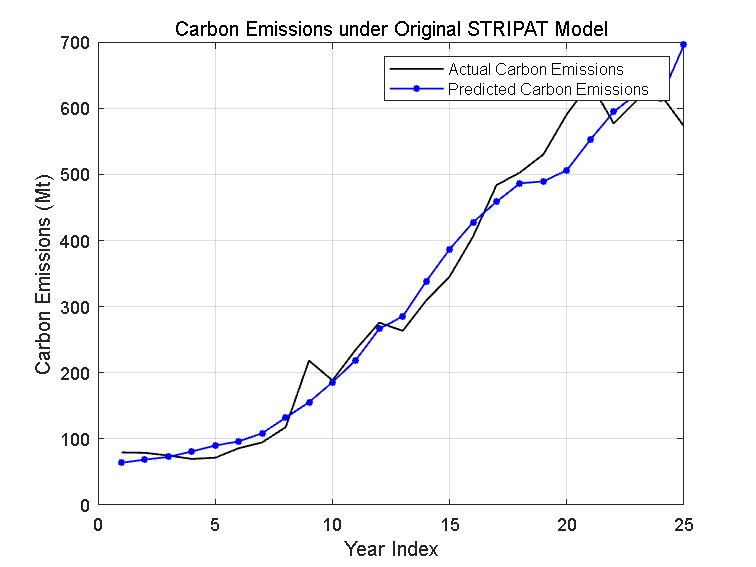


% 原始结果曲线图
figure;
plot(exp(dataTableLog.LogEmission), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Original STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 改良STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Shaanxi_data.xlsx'; 
dataTable = readtable(filename);

% 数据提取与转换 重新提取一下 变原单位
dataGDP = dataTable.Per_capita_GDP_yuan(1:25);
dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataSecond = dataTable.Value_added_of_the_secondary_industry_billion(1:25) * 1e9;
dataCE = dataTable.CarbonEmissions_mt(1:25);
energyconsumption = (dataTable.Coal_consumption_10000_tons(1:25) + dataTable.Coke_consumption_10000_tons(1:25) + dataTable.Fuel_oil_consumption_10000_tons(1:25)) * 1e4;
dataNaturalgas = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25) * 1e9;
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25) * 1e8;
hydroPower = dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
totalPower = dataTable.Total_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
dataWaterPercent = (hydroPower ./ totalPower) * 100;

% 数据标准化处理
dataMatrix = [dataCE, dataGDP, dataPopulation, dataSecond, energyconsumption, dataNaturalgas, dataTechnology, dataWaterPercent];

dataLog = log(dataMatrix+1);
% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 定义变量名称
variableNames = {'CarbonEmissions', 'GDP', 'Population', 'SecondaryIndustry', 'EnergyConsumption', 'NaturalGas', 'TechnologyTransactions', 'HydroPowerPercentage'};

% 输出相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                              CarbonEmissions      GDP       Population    SecondaryIndustry    EnergyConsumption    NaturalGas    TechnologyTransactions    HydroPowerPercentage
                              _______________    ________    __________    _________________    _________________    __________    ______________________    ____________________

    CarbonEmissions                     1         0.98489         0.92          0.98518              0.99361          0.87781              0.95258                 -0.61203      
    GDP                           0.98489               1       0.9514          0.99809              0.99018          0.90793              0.97919                 -0.58239      
    Population                       0.92          0.9514            1          0.93187               0.9178          0.82066              0.97497                 -0.53779      
    SecondaryIndustry             0.98518         0.99809      0.93187                1              0.99217 

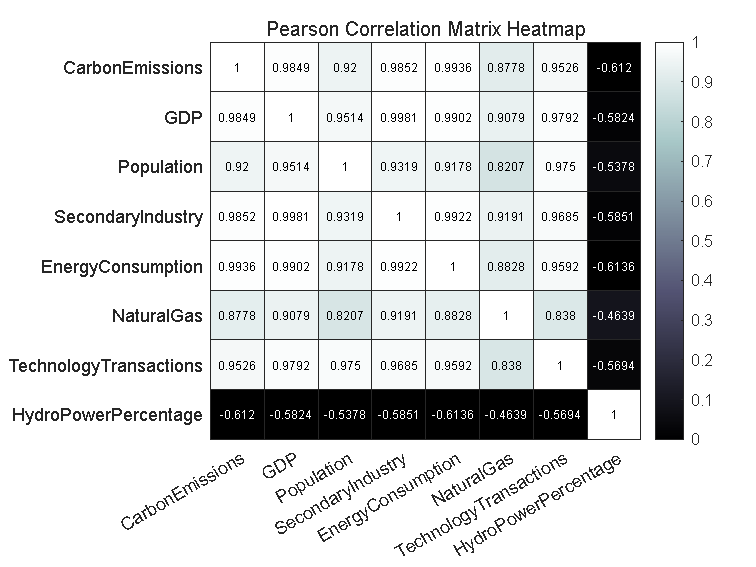


% 热力图
figure; % jet太难看了 换个颜色 winter也难看 pink不错 就bone了
%mycolor = [0.474509803921569,0.650980392156863,0.807843137254902;...
% 0.682352941176471,0.823529411764706,0.898039215686275;...
 %0.941176470588235,0.972549019607843,0.862745098039216;...
 %0.992156862745098,0.968627450980392,0.705882352941177;...
 %1,0.901960784313726,0.603921568627451];
h = heatmap(variableNames, variableNames, correlationMatrix);
h.Title = 'Pearson Correlation Matrix Heatmap';
h.Colormap = bone; 
h.ColorScaling = 'scaledcolumns'; 

%colormap(gca,mycolor);


% 创建数据表格
variableNames = {'LogCE','LogGDP', 'LogPopulation', 'LogSecond',  'LogEnergyConsumption', 'LogNaturalGas', 'LogTechnology', 'LogWaterPercent'};
dataTableLog = array2table(dataLog, 'VariableNames', variableNames);

% 拟合模型
lm_formula = 'LogCE ~ LogPopulation + LogGDP + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogCE ~ 1 + LogGDP + LogPopulation + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent

估计系数:
                            Estimate        SE         tStat       pValue  
                            _________    ________    _________    _________

    (Intercept)                10.299      148.14     0.069519      0.94539
    LogGDP                     1.0871      1.2273       0.8858      0.38809
    LogPopulation            -0.47434      7.5491    -0.062834      0.95063
    LogSecond                -0.87735      1.0368      -0.8462      0.40919
    LogEnergyConsumption       1.1505     0.35028       3.2844    0.0043746
    LogNaturalGas            0.007025    0.070671     0.099403      0.92198
    LogTechnology           -0.098917    0.090149      -1.0973      0.28782
    LogWaterPercent         -0.021347     0.08091     -0.26384      0.79507


观测值数目: 25，误差自由度: 17
均方根误差: 0.101
R 方: 0.989，调整 R 方 0.985
F 统计量(常量模型): 228，p 值 = 1.54e-15


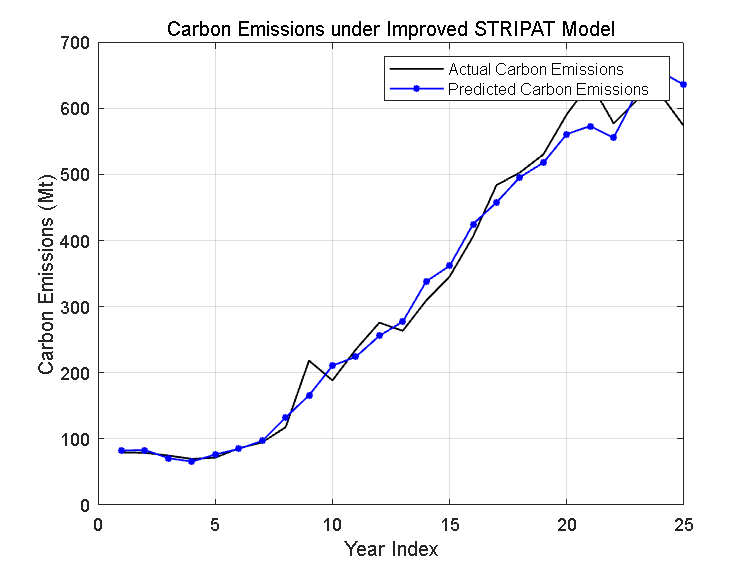


lmCoefficients = model.Coefficients.Estimate; % 存储系数
% 结果曲线图
figure;
plot(exp(dataTableLog.LogCE), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Improved STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 将预测得到的各个YPred的LSTM值带入到改良STRIPAT模型

YPredLogGDP = log(YPredGDP).';  % 取对数并转置
YPredLogPopulation = log(YPredPopulation).';
YPredLogSecond = log(YPredSecond).';
YPredLogEnergy = log(YPredEnergy).';
YPredLogNaturalGas = log(YPredNaturalgas).';
YPredLogTechnology = log(YPredTechnology).';
YPredLogWaterPercent = log(YPredWaterpercent).';
dataCE = dataTable.CarbonEmissions_mt(1:25); % 真实碳排放数据
Years = dataTable.Year(1:25); 

% 计算预测的碳排放

PredictedLogCE = lmCoefficients(1) + lmCoefficients(3) * YPredLogGDP + lmCoefficients(2) * YPredLogPopulation + ...
                 lmCoefficients(4) * YPredLogSecond + lmCoefficients(5) * YPredLogEnergy + ...
                 lmCoefficients(6) * YPredLogNaturalGas + lmCoefficients(7) * YPredLogTechnology + ...
                 lmCoefficients(8) * YPredLogWaterPercent;
% 将对数形式的预测碳排放转换回原始尺度
PredictedCE_1 = exp(PredictedLogCE);
PredictedCE = (PredictedCE_1)/1e5+400;
% 输出预测结果
disp('Predicted CarbonEmissions for future years:');

Predicted CarbonEmissions for future years:


disp(PredictedCE);

   1.0e+02 *

   6.0562 + 0.0000i
   5.9532 + 0.0000i
   5.8591 + 0.0000i
   5.7684 + 0.0000i
   5.6998 + 0.0000i
   5.6450 + 0.0000i
   5.6104 + 0.0000i
   5.5941 + 0.0000i
   5.5981 - 0.1073i
   5.5044 - 0.1010i
   5.4593 - 0.0980i
   5.4424 - 0.0969i
   5.4635 + 0.0000i
   5.4019 + 0.0000i
   5.4284 - 0.0959i
   5.5539 + 0.0000i
   5.4096 + 0.0000i
   5.5418 - 0.1036i
   5.4235 + 0.0000i
   5.4383 + 0.0000i
   5.4225 + 0.0000i
   5.4388 + 0.0000i
   5.4223 + 0.0000i
   5.4198 + 0.0000i
   5.4066 + 0.0000i
   5.4121 + 0.0312i
   5.4246 + 0.0314i
   5.4323 + 0.0316i



% 绘制实际与预测的碳排放量对比图
figure;
plot(Years, dataCE, 'k', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Actual Carbon Emissions');
hold on;
plot(Years(1) + (25:52), PredictedCE, 'r*-', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Predicted Carbon Emissions');

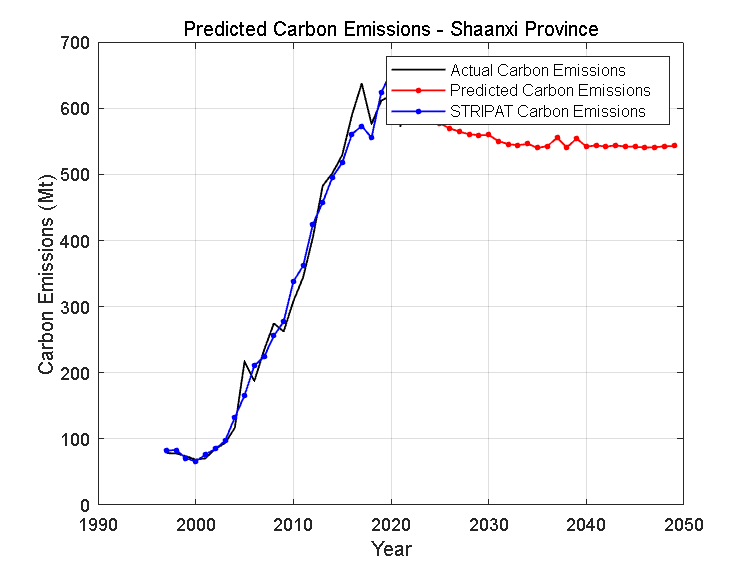

%STRIPATPred=exp(PredictedCE);
plot(Years(1)+ (0:24), exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'STRIPAT Carbon Emissions');
title('Predicted Carbon Emissions - Shaanxi Province');
xlabel('Year');
ylabel('Carbon Emissions (Mt)');
legend show;
grid on;
hold off;